# Atividade 06

## Overview

Como estamos lidando com um problema de thermallcouple, estamos lidando com um cenario de medicao de temperatura a partir de um diferencial de temp (entre algo que queremos medir e algo que sabemos a temp), gerando entao uma tensao.

No nosso problema, entretanto, nao estamos usando a referencia como sendo $0^\circ C$, mas sim a temperatura ambiente $23 \pm 2^\circ C$. Isso significa que teremos que utilizar a lei de temperaturas intermediarias, dada por:


$$e_{13} = e_{12} + e_{23}$$


Que implica que, a tensao de saida entre as temperaturas 1 e 3 'e igual a soma das tensoes de saida oriundas das diferencas entre as temperaturas 1 e 2, 2 e 3.

## Temperatura Media

Para o problema de temperatura media, podemos considerar que:

- O Delta de temperatura entre $T_3 = 0 \rightarrow T_2 = 23$ gera uma tensao $e_{23}$, que sabemos por ser tableado no datasheet.

- Ja o Delta de temperatura entre $T_2 = 23 \rightarrow T_1 = ?$ gera uma tensao $e_{12}$ que foi medida

- A partir das duas anteriores, e da lei de temperaturas intermediarias, temos que $e_{13}$ e a soma das tensoes supracitadas (logo sabemos), e eh referente ao Delta de Tensao oriundo de $T_3 = 0 \rightarrow T_1 = target$. Como temos a tensao para a referencia de $0^\circ$, que eh tabelada, podemos achar o valor de $T_1$.

### Problem Data

#### **Filed Data**

%% CONSTANTS
resolution = 0.01;     % Resolução do sensor
uncertainties = 1e-2;  % Incerteza do Sensor
ref_temp = 23;         % Temperatura alvo
ref_temp_var = 2;      % Variação de temperatura alvo

%% SENSOR DATA
sensor_data = readtable('data/Data06.csv'); 
sensor_data.Properties.VariableNames = {'time' 'tension'};

#### **Thermal Couple Table Data**

e_23_0 = 1.174;        % Tensao (mv) para 23C, com 0C como reff

### Analise de Tensao - Sensor Thermalcouple

A Base para a analise de tensao gerada pelo Delta de Temperatura eh a media, desvio padrao e calculo de incertezas associadas, como demosntrado pela formula abaixo (para posteriormente calcular a propagacao de todas as incertezas para a conversao tensao - temperatura).


$$x'  \approx \bar x \pm u_{\bar x} \Rightarrow \begin{cases} u_{\bar x} = &  t_{v, p} \sqrt{s_{\bar x} ^ 2 + b_{\bar x} ^ 2} \\ s_{\bar x} = &\frac{s_x}{\sqrt{N} }\\ b_{\bar x}=&\left[ \sum b_{\bar x, i}^ 2\right]^{1/2} \end{cases}$$
 

N = height(sensor_data);                  % Number of collected points

e_T_23 = mean(sensor_data.tension);       % Mean of measured Voltge
s_x = std(sensor_data.tension) / sqrt(N); % Standard mean deviation
b_x = sqrt((resolution./2).^2 + (uncertainties .* e_T_23).^2); % Instrumental Uncertanties

### Conversao Tensao - Temperatura Media e Intervalo de Confianca

A fim de obter o valor de temperatura media a partir da tensao, com um intervalo de conficanca de 95% temos que levar em consideracao a propagacao de incerteza, dada por:


$$T'  = f(e_{13}, T_{reff}) \approx f(e_{13}) \therefore T' = \bar T \pm t_{v, p}u_{\bar T} \Rightarrow \begin{cases} u_{\bar T} =& \left[\sum_{k=1} (\theta_k u_{\bar x, k})^2 \right]^{1/2} \\ \theta_{k} =& \frac{d}{dX_k} T \big|_{x=\bar x} \\ u_{\bar x, k} =& \sqrt{s_{\bar x, k}^2 + b_{\bar x, k}^2} \end{cases}$$


Como temos que a temperatura eh uma funcao da tensao que esta sendo medida (como mostrada pelas tabelas do thermal couple - J jutanmente com a lei das temperaturas intermediarias), temos que, para calcularmos aproximadamente a temperatura real temos que:

- Calcular a Temperatura Media a partir dos valores medios de tensao e temperatura medidos.

- Calcular as incertezas (tanto aleatorias quanto sistematicas/instrumentais) de cada variavel

- Modelar a Tensao em funcao das variaveis com fonte de incerteza, para que possamos calcular $\theta$ (referente a propagacao de incertezas)

- Unir todas as incertezas como mostrado pela formula do $U_{\bar T}$.

#### Curve Fitting - Modelagem de Temperatura em funcao de tensao

Como ja fizemos anteriormente as partes 1 e 2 (a partir dos dados fornecidos) precisamos entao passar para a parte 3, e modelar a tensao em funcao das variaveis de fonte de incerteza. Como estamos lidando com um thermal couple, temos que a influencia das incertezas de $T_{reff}$ se propagam, assim como as incertezas das medicoes, pois a tensao eh composta por ambas as tensoes (devido a lei de tensoes intermediarias). Logo o curve fitting dos dados do thermalcouple - J Type dados pelo NIST ([National Institute of Standards And Tecnologis](https://srdata.nist.gov/its90/download/type_j.tab)) vai nos dar uma funcao Temperatura $T = f(v_{data}, v_{t_{reff}})$.

Ao calcularmos o ponto de interesse (para que possamos fazer um curve fitting em um range mais especifico) temos:

e_T_0 = e_23_0 + e_T_23

e_T_0 = 2.3856

Para tal valor, temos os seguintes pontos tabelados:

NIST_THERMAL_CP_TEMP = 40:1:50;
NIST_THERMAL_CP_DATA = [2.059  2.111  2.164  2.216  2.269  2.322  2.374  2.427  2.480  2.532  2.585];

Ao plotarmos vemos um comportamento extremamente linear, como visto abaixo:

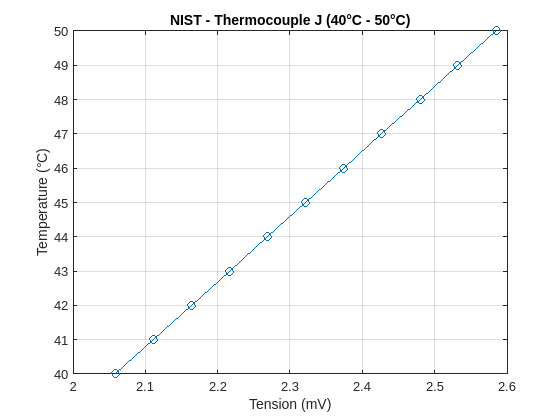

plot(NIST_THERMAL_CP_DATA, NIST_THERMAL_CP_TEMP, Marker="o");
title('NIST - Thermocouple J (40°C - 50°C)');
ylabel('Temperature (°C)'), xlabel('Tension (mV)');
grid on;

Que, ao fazermos o curve fitting, resulta na seguinte expressao:


$$T(v) = 19 v +0.8837$$


fitted_curve = fit(NIST_THERMAL_CP_DATA', NIST_THERMAL_CP_TEMP', 'poly1')

fitted_curve =      Linear model Poly1:
     fitted_curve(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =          19  (18.98, 19.03)
       p2 =      0.8837  (0.8264, 0.941)

Ja o $v$ eh dado por:


$$v = v_{data} + v_{Temp_{reff}}$$


Onde $v_{temp_{reff}}$, por sua vez, eh dado pela seguinte curva:

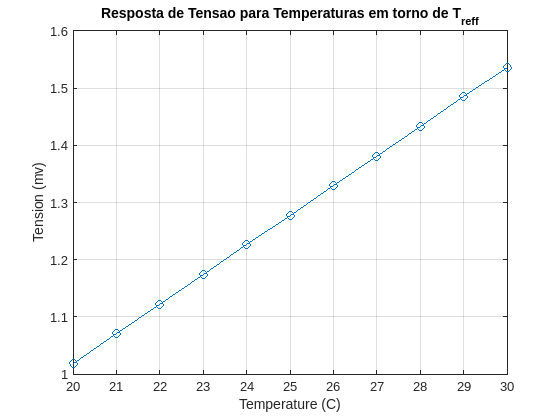

TABLE_TEMP = 20:30;
TABLE_VOLTAGE = [1.019  1.071  1.122  1.174  1.226  1.277  1.329  1.381  1.433  1.485  1.537];

plot(TABLE_TEMP, TABLE_VOLTAGE, Marker="o");
title('Resposta de Tensao para Temperaturas em torno de T_{reff}');
ylabel('Tension (mv)'), xlabel('Temperature (C)');
grid on;


ref_temp_curve = fit(TABLE_TEMP', TABLE_VOLTAGE', 'poly1')

ref_temp_curve =      Linear model Poly1:
     ref_temp_curve(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =     0.05178  (0.0517, 0.05186)
       p2 =    -0.01691  (-0.01898, -0.01484)

Resultando na seguinte formulacao geral para a tensao em funcao da temperatura de referencia e tensao medida:


$$T(v, T_{reff}) = 19 [v + (0.05178 \cdot T_{reff} - 0.01691) ] +0.8837$$


#### Associacao de Incertezas

A partir da funcao obtida temos que:

% Calculo de Temperatura media a partir da tensao coletada
target_temp = fitted_curve(e_T_0); 

% Calculo das Incertezas Propagadas
syms v t_ref;
T_v_t_reff = 19 .* (v + (0.05178 .* t_ref - 0.01691)) + 0.8837;

theta_v = vpa(subs(diff(T_v_t_reff, v), [v t_ref], [e_T_0 23]));
theta_t = vpa(subs(diff(T_v_t_reff, t_ref),[v t_ref], [e_T_0 23]));

s_T = sqrt((theta_t*2).^2 + (theta_v*s_x).^2);
b_T = sqrt((theta_v*b_x).^2 + (theta_v*resolution./2).^2 + (theta_v*e_T_23*uncertainties).^2);

% Calculo da Incerteza Total
u_T = sqrt(s_T + b_T);
t = tinv(0.975, N-1);
target_temp, t*u_T

target_temp = 46.2130

$$ans = 2.9956852126021914005442125662995$$